##  Included in Workspace

close all; clear all;clc
basepath=fullfile(getenv('HOME'), 'MATLAB', 'Spatial-Context-KAC-Association');
data_dir='D:\dclde2013';

%kjp basepath and datadir
basepath ='C:\BitBucketRepositories\Spatial Context KAC Association';
data_dir='D:\Data\DCLDE2013\';

cd(fullfile(basepath, 'MatlabCode'));

% Folder containing the neural network output
detectionsLocation = fullfile(basepath, 'NeuralNetworkOutput');

% Parameters
fs =2000;
NNoutput = dir(fullfile(detectionsLocation, '*.txt'))

NNoutput = 7×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum




%% All the validation files
truthFiles = dir(fullfile(data_dir, 'TruthFiles', '*.csv'));


% List of sound files
tiny = true;
if tiny
    cwd = fullfile(data_dir, 'DCLDE_2013_10Channel\Day1'); % testing on one day
    
    % Only load first dayfile
    NNoutput=NNoutput(1);
    truthFiles = truthFiles(1);

else
    cwd = fullfile(data_dir, 'DCLDE_2013_10Channel\All'); % running on all days
   
end
file_list=(  dir(fullfile(cwd, '*.aif')));







% Reference and total number of channels
ref_chan=10;
num_chan=10;

% Load DCLDE meta data
dclde_2013_meta = xlsread(fullfile(data_dir, 'DCL2013_NEFSC_SBNMS_200903_metadata.xlsx'));

## From the Neural Network output, add the necessary file contents to allign with Raven selection tables

detectionsOut =[]; % empty variable to stack across selection table days
for ii = 1:length(NNoutput)

    % A bit unclear here, it looks like we are adding in the number of days
    % to find offsets as if they were into a stream of days, but the Raven
    % selection files have timestamps that appear to be offsets into a
    % single day.
    fname = fullfile(NNoutput(ii).folder, NNoutput(ii).name)
    detections = readtable(fname);
    detections.streamSampleStart = round(detections.BeginTime_s_*fs)+(24*(ii-1)*60*60*fs)+1;
    detections.streamSampleStop = detections.streamSampleStart+(fs*2);
    detections = sortrows(detections,'streamSampleStart','ascend');
    detections.date = ones([height(detections), 1])*datenum(NNoutput(ii).name(end-11:end-4), 'yyyymmdd');
    detections.BeginTime_s_= detections.BeginTime_s_+((ii-1)*24*60*60);
    detections.EndTime_s_= detections.EndTime_s_+((ii-1)*24*60*60);
    detections.Selection= detections.Selection+size(detectionsOut,1);
    chanCall=ones(1,10);
    
    detectionsOut = [detectionsOut; detections];
    
    
end

fname = 'C:\BitBucketRepositories\Spatial Context KAC Association\NeuralNetworkOutput\upcall_seltab_20090328.txt'


detectionsOut = sortrows(detectionsOut,'streamSampleStart','ascend');
detections = detectionsOut;
clear detectionsOut


## Load the Metadata associated with each hydrophone. 

load the data and inspect the hydrophone geometry. A structure of the hydrophone information is then created for the association process

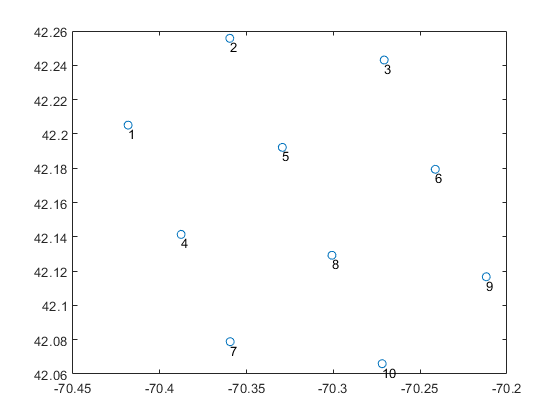


% Create labels for plotting locations (undocumented function)
labels=sprintfc('%d',1:10);

plot(dclde_2013_meta(:,12), dclde_2013_meta(:,11), 'o')
text(dclde_2013_meta(:,12), dclde_2013_meta(:,11),labels,'VerticalAlignment','top','HorizontalAlignment','left')


% Convert the meta data to a structure in the format that the
% GPL/localisation code expects

hydrophone_struct= struct();
for ii=1:size(dclde_2013_meta,1)
    hydrophone_struct(ii).name = num2str(dclde_2013_meta(ii,1));
    hydrophone_struct(ii).location = dclde_2013_meta(ii,[11:12]);
    hydrophone_struct(ii).depth= abs(dclde_2013_meta(ii, 13));
    hydrophone_struct(ii).channel=ii;
    
end




## Create a list of all the soundfiles and pull the starttime of each file from the filename


file_listTable = struct2table(file_list); % List of files

% Convert character to matlab date for start time
file_listTable.MatlabDate = cell2mat(vertcat(cellfun(@(x) datenum(x(end-18:end-4), 'yyyymmdd_HHMMSS'), ...
    file_listTable.name, 'UniformOutput', false)));

% Samples into the entire stream (full day for testing or multiple days if running on full dataset)
file_listTable.SampleStrt = fs*60*60*24*(file_listTable.MatlabDate-floor(min(file_listTable.MatlabDate)));

% Seconds inot the stream
file_listTable.SecStart = (file_listTable.MatlabDate-floor(file_listTable.MatlabDate))*60*60*24;
file_listTable.SampStop =file_listTable.SampleStrt+(15*60*fs);



## Set up the meta data into a structure

%get the x corr times between hydrophone 10 (primary) and others
for ii=1:num_chan
    % distance between the primary and secondary
    dist(ii) = vdist2(hydrophone_struct(10).location(1),...
        hydrophone_struct(10).location(2),...
        hydrophone_struct(ii).location(1),...
        hydrophone_struct(ii).location(2));
end
hydDelay = dist/1350; % delay between each hdyrophone pair in seconds

% convert delays from seconds to samples
hydDelay = round(hydDelay * fs);

% get max delay
% Add some slack, if this works a more systematic approach will be warented
max_delay = max(hydDelay)+2; 

##  Create the associations using KAC code

This bit creates the asscoations of calls between the reference channel and those on the adjacent channels using Kathy Cortipassi cross correlation code. Returns tables for each returned variable wthere the rows are the number of detections on the reference channel and the columns are the number of hydrophones in the array minus 1. Blank/NA cells indicate where no associations were present.

Delays - time in seconds between the reference and other detections on other channels

Dex - Index of each of the detections that has been associated

crossScores -cross correlation scores between the referene detection and the adjacent ones

arrivalArray- arrival time (in seconds) of each of the detections


delays = nan(sum((detections.Channel==10)), 10); 
dex = delays;
crossScores = dex;
arrivalArray = dex;
detectionsRef =detections(detections.Channel==ref_chan,:);


% Primary detections
for ii =1:height(detectionsRef)
    
    [delays(ii,:), dex(ii,:), crossScores(ii,:),val] = ...
        createAssociations(detections, ii, file_listTable,hydDelay, ref_chan, fs);
    
    if ~isempty(val)
        valueout(ii)=val;
    end
    dex(ii,ref_chan)=detectionsRef.Selection(ii);
    
    ii;
 
end


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpts =

     []


beginBuffpt

## Remove associations where multiple primary channel detections were linked to secondary detections

Because association is based on cross correlation only one deteciton on a reference channel may be correlated to multiple calls on the primary channel. See dex rows 45:51 (45:51,:)

dex(45:51,5:10)

ans =          NaN         NaN        4963         NaN         NaN        7588
         NaN         NaN        4965        6091         NaN        7589
         NaN         NaN        4965        6092         NaN        7590
         NaN         NaN        4965        6092         NaN        7591
         NaN         NaN        4967         NaN         NaN        7592
         NaN         NaN        4968        6095         NaN        7593
         NaN         NaN        4969        6096         NaN        7594




%%%%%%%%%% This actually doesn't seem to help at all but should be done regardles. 


for jj =1:9
    
    [counts, ids] = groupcounts(dex(~isnan(dex(:,jj)),jj));
    doubleBooked =ids(counts>1);
    
    % Step through the double booked values, find the highest correlationa call
    % and for all othe rprimary calls, remove the association
    
    for ii=1:length(doubleBooked)
        
        callId = doubleBooked(ii);
        primaryCalldexs = find(dex(:,jj)==callId);
        
        % get the cross correlation scores
        corrscores = vertcat(valueout(primaryCalldexs).all_pk_xcorr_norm);
        
        % index of the strongest correlation
        [~, keepIdx] =max(corrscores(:,jj));
        primaryCalldexs(keepIdx)=[];
        
        % Allow that one to stay but clear out the arrival array, dex, and
        % cross scores for the remaining double booked detections
        delays(primaryCalldexs,jj)=nan;
        dex(primaryCalldexs,jj)=nan;
        crossScores(primaryCalldexs,jj)=nan;
        
        
    end
end

%house keeping
clear counts ids doubleBooked callId primaryCalldexs corrscores keepIdx


## Prep the validation data

Raven selection tables with all annotations of the reference channel. Simulation structure is only used for the temporal context (as in linking acoustic encounters)




truthStream =[];
for ii=1:length(truthFiles)
    
    truthtemp = readtable(fullfile(truthFiles(ii).folder, truthFiles(ii).name));
    truthtemp=truthtemp(:,1:7);
    
    
    if ii>1
        truthtemp.Selection=truthtemp.Selection+height(truthStream);
    end
    
    truthtemp.mstart = datenum(truthFiles(ii).name(7:14), 'yyyymmdd')+truthtemp.BeginTime_s_/86400;
    truthtemp.mend = datenum(truthFiles(ii).name(7:14), 'yyyymmdd')+truthtemp.EndTime_s_/86400;
    truthtemp.mid = (truthtemp.mend+truthtemp.mstart)/2;
    truthtemp.Sec = (truthtemp.mstart-min(truthtemp.mstart))*60*60*24+(ii-1)*24*60*60;
    truthtemp.DetectorScore = zeros([height(truthtemp) 1 ]);
    truthtemp.BeginTime_s_= truthtemp.BeginTime_s_+((ii-1)*24*60*60);
    truthtemp.EndTime_s_= truthtemp.EndTime_s_+((ii-1)*24*60*60);
    truthStream=[truthStream; truthtemp];
    clear truthtemp
    ii;
end


truth = truthStream;
clear truthStream truthtemp truthFiles


%% Set up the simulation structure
arrivalArray = detectionsRef.BeginTime_s_*ones(1,10)+delays;
arrivalArray(:,10)=detectionsRef.BeginTime_s_;

simStruct = struct();
simStruct.arrivalArray = [arrivalArray(:,ref_chan) arrivalArray(:,1:end-1)];
simStruct.TDOA_vals = delays;


simStruct.fs =fs;
simStruct.PosUncertsigma = 0.0004^2 +.1^2 + .3^2; % seconds see EM Nosal 20
simStruct.PosUncertsigma = 0.0067^2 +.003^2 + .25^2; % seconds see EM Nosal 20- R position, ssp, arrival time
simStruct.drift = 0.25; % clock drift uncertainty
simStruct.c =1500;  % speed of sound
simStruct.truncateKm=18; % replaced by half normal function, previously maximum detection distance
simStruct.maxEltTime = 30*60; % Maximum elapsed time between detections to make another encounter
simStruct.s = 3;% maximum swim speed of the animal in m/s

refChanScores =detections.Score(detections.Channel==ref_chan);
simStruct.RefScores = refChanScores;

% Match the truth files to the 'pruned' detections to establish what the
% truth is
simStruct.dex = dex;
[simStruct.pruned truth]= validateDetection(truth, simStruct, ref_chan);

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

jj = 10

jj = 11

jj = 13

jj = 14

jj = 15

jj = 16

jj = 17

jj = 18

jj = 20

jj = 21

jj = 22

jj = 23

jj = 25

jj = 26

jj = 27

jj = 28

jj = 29

jj = 30

jj = 31

jj = 33

jj = 35

jj = 36

jj = 37

jj = 38

jj = 40

jj = 41

jj = 42

jj = 43

jj = 44

jj = 45

jj = 46

jj = 47

jj = 48

jj = 49

jj = 50

jj = 51

jj = 52

jj = 54

jj = 55

jj = 56

jj = 57

jj = 58

jj = 59

jj = 60

jj = 64

jj = 65

jj = 66

jj = 67

jj = 73

jj = 76

jj = 77

jj = 78

jj = 79

jj = 81

jj = 83

jj = 84

jj = 85

jj = 87

jj = 88

jj = 89

jj = 90

jj = 91

jj = 92

jj = 93

jj = 94

jj = 95

jj = 96

jj = 98

jj = 99

jj = 100

jj = 101

jj = 102

jj = 103

jj = 104

jj = 105

jj = 106

jj = 107

jj = 108

jj = 109

jj = 110

jj = 111

jj = 112

jj = 113

jj = 114

jj = 115

jj = 116

jj = 117

jj = 118

jj = 119

jj = 120

jj = 121

jj = 122

jj = 123

jj = 124

jj = 125

jj = 126

jj = 127

jj = 128

jj = 130

jj = 133

jj = 134

jj = 135

jj = 138

jj = 139

jj = 140

jj = 141

jj = 142

jj = 144

jj = 145

jj = 146

jj = 147

jj = 148

jj = 149

jj = 151

jj = 152

jj = 153

jj = 154

jj = 155

jj = 156

jj = 157

jj = 158

jj = 159

jj = 160

jj = 161

jj = 162

jj = 163

jj = 164

jj = 165

jj = 166

jj = 167

jj = 168

jj = 169

jj = 170

jj = 171

jj = 172

jj = 173

jj = 174

jj = 175

jj = 176

jj = 177

jj = 178

jj = 179

jj = 180

jj = 181

jj = 183

jj = 185

jj = 186

jj = 187

jj = 188

jj = 189

jj = 190

jj = 191

jj = 192

jj = 193

jj = 194

jj = 195

jj = 196

jj = 197

jj = 198

jj = 199

jj = 200

jj = 201

jj = 204

jj = 205

jj = 206

jj = 207

jj = 208

jj = 209

jj = 210

jj = 212

jj = 213

jj = 214

jj = 215

jj = 216

jj = 217

jj = 218

jj = 219

jj = 220

jj = 221

jj = 222

jj = 223

jj = 224

jj = 225

jj = 226

jj = 227

jj = 228

jj = 229

jj = 230

jj = 231

jj = 232

jj = 233

jj = 234

jj = 235

jj = 236

jj = 237

jj = 238

jj = 239

jj = 240

jj = 241

jj = 242

jj = 243

jj = 244

jj = 245

jj = 246

jj = 247

jj = 248

jj = 249

jj = 250

jj = 251

jj = 252

jj = 253

jj = 255

jj = 256

jj = 257

jj = 258

jj = 259

jj = 260

jj = 261

jj = 262

jj = 263

jj = 264

jj = 265

jj = 266

jj = 267

jj = 268

jj = 269

jj = 270

jj = 271

jj = 273

jj = 274

jj = 275

jj = 276

jj = 277

jj = 282

jj = 284

jj = 285

jj = 287

jj = 289

jj = 290

jj = 291

jj = 294

jj = 295

jj = 297

jj = 301

jj = 303

jj = 305

jj = 307

jj = 308

jj = 313

jj = 314

jj = 315

jj = 316

jj = 317

jj = 318

jj = 319

jj = 320

jj = 321

jj = 322

jj = 323

jj = 324

jj = 330

jj = 332

jj = 333

jj = 334

jj = 335

jj = 337

jj = 338

jj = 339

jj = 340

jj = 342

jj = 343

jj = 344

jj = 345

jj = 346

jj = 347

jj = 348

jj = 349

jj = 350

jj = 351

jj = 352

jj = 353

jj = 354

jj = 355

jj = 356

jj = 357

jj = 358

jj = 359

jj = 360

jj = 361

jj = 362

jj = 363

jj = 364

jj = 365

jj = 366

jj = 367

jj = 368

jj = 369

jj = 370

jj = 371

jj = 372

jj = 373

jj = 374

jj = 375

jj = 376

jj = 377

jj = 378

jj = 379

jj = 380

jj = 381

jj = 382

jj = 383

jj = 384

jj = 385

jj = 386

jj = 387

jj = 388

jj = 389

jj = 390

jj = 391

jj = 392

jj = 393

jj = 394

jj = 396

jj = 397

jj = 398

jj = 399

jj = 400

jj = 401

jj = 402

jj = 403

jj = 404

jj = 405

jj = 406

jj = 408

jj = 409

jj = 410

jj = 411

jj = 412

jj = 413

jj = 414

jj = 415

jj = 416

jj = 417

jj = 418

jj = 419

jj = 420

jj = 421

jj = 422

jj = 423

jj = 424

jj = 425

jj = 426

jj = 427

jj = 428

jj = 430

jj = 431

jj = 439

jj = 440

jj = 449

jj = 450

jj = 460

jj = 475

jj = 478

jj = 480

jj = 481

jj = 482

jj = 483

jj = 485

jj = 486

jj = 487

jj = 488

jj = 489

jj = 490

jj = 493

jj = 494

jj = 495

jj = 496

jj = 498

jj = 499

jj = 501

jj = 502

jj = 503

jj = 504

jj = 505

jj = 506

jj = 507

jj = 508

jj = 509

jj = 510

jj = 511

jj = 512

jj = 513

jj = 514

jj = 515

jj = 516

jj = 518

jj = 519

jj = 520

jj = 521

jj = 522

jj = 523

jj = 525

jj = 526

jj = 527

jj = 528

jj = 537

jj = 540

jj = 542

jj = 543

jj = 551

jj = 552

jj = 553

jj = 554

jj = 555

jj = 556

jj = 558

jj = 561

jj = 562

jj = 563

jj = 566

jj = 567

jj = 568

jj = 569

jj = 570

jj = 571

jj = 572

jj = 573

jj = 574

jj = 576

jj = 578

jj = 580

jj = 583

jj = 584

jj = 585

jj = 586

jj = 588

jj = 589

jj = 590

jj = 591

jj = 592

jj = 594

jj = 596

jj = 601

jj = 608

jj = 610

jj = 611

jj = 613

jj = 614

jj = 615

jj = 618

jj = 619

jj = 624

jj = 628

jj = 629

jj = 630

jj = 631

jj = 632

jj = 638

jj = 639

jj = 640

jj = 641

jj = 642

jj = 643

jj = 644

jj = 645

jj = 646

jj = 648

jj = 654

jj = 664

jj = 665

jj = 667

jj = 670

jj = 671

jj = 672

jj = 673

jj = 675

jj = 678

jj = 679

jj = 680

jj = 681

jj = 682

jj = 685

jj = 686

jj = 687

jj = 692

jj = 694

jj = 698

jj = 700

jj = 701

jj = 702

jj = 704

jj = 705

jj = 706

jj = 707

jj = 708

jj = 709

jj = 710

jj = 712

jj = 714

jj = 715

jj = 716

jj = 717

jj = 718

jj = 720

jj = 721

jj = 722

jj = 723

jj = 724

jj = 725

jj = 726

jj = 727

jj = 728

jj = 729

jj = 730

jj = 731

jj = 732

jj = 734

jj = 736

jj = 737

jj = 738

jj = 739

jj = 740

jj = 742

jj = 743

jj = 744

jj = 745

jj = 746

jj = 748

jj = 749

jj = 750

jj = 751

jj = 752

jj = 753

jj = 754

jj = 755

jj = 756

jj = 757

jj = 758

jj = 759

jj = 762

jj = 763

jj = 765

jj = 766

jj = 767

jj = 768

jj = 769

jj = 770

jj = 771

jj = 777

jj = 779

jj = 785

jj = 787

jj = 789

jj = 791

jj = 793

jj = 794

jj = 795

jj = 797

jj = 798

jj = 799

jj = 801

jj = 804

jj = 806

jj = 807

jj = 810

jj = 811

jj = 813

jj = 814

jj = 815

jj = 816

jj = 818

jj = 819

jj = 820

jj = 821

jj = 822

jj = 827

jj = 828

jj = 829

jj = 830

jj = 831

jj = 832

jj = 833

jj = 834

jj = 835

jj = 837

jj = 840

jj = 841

jj = 842

jj = 843

jj = 844

jj = 845

jj = 846

jj = 848

jj = 851

jj = 853

jj = 855

jj = 856

jj = 857

jj = 858

jj = 860

jj = 866

jj = 867

jj = 868

jj = 875

jj = 876

jj = 879

jj = 884

jj = 885

jj = 886

jj = 887

jj = 888

jj = 889

jj = 890

jj = 892

jj = 893

jj = 895

jj = 897

jj = 898

jj = 899

jj = 900

jj = 901

jj = 902

jj = 903

jj = 904

jj = 905

jj = 906

jj = 908

jj = 910

jj = 911

jj = 912

jj = 913

jj = 914

jj = 915

jj = 917

jj = 918

jj = 919

jj = 920

jj = 921

jj = 922

jj = 923

jj = 924

jj = 925

jj = 927

jj = 928

jj = 929

jj = 930

jj = 932

jj = 933

jj = 934

jj = 935

jj = 936

jj = 937

jj = 938

jj = 939

jj = 947

jj = 948

jj = 949

jj = 951

jj = 952

jj = 953

jj = 954

jj = 955

jj = 956

jj = 957

jj = 958

jj = 959

jj = 960

jj = 962

jj = 964

jj = 965

jj = 966

jj = 967

jj = 968

jj = 970

jj = 971

jj = 972

jj = 973

jj = 975

jj = 977

jj = 978

jj = 979

jj = 980

jj = 981

jj = 982

jj = 983

jj = 984

jj = 986

jj = 987

jj = 988

jj = 989

jj = 990

jj = 991

jj = 992

jj = 993

jj = 994

jj = 995

jj = 996

jj = 997

jj = 998

jj = 999

jj = 1001

jj = 1002

jj = 1003

jj = 1004

jj = 1005

jj = 1009

jj = 1010

jj = 1011

jj = 1013

jj = 1015

jj = 1016

jj = 1017

jj = 1019

jj = 1020

jj = 1022

jj = 1023

jj = 1024

jj = 1025

jj = 1026

jj = 1027

jj = 1028

jj = 1029

jj = 1030

jj = 1031

jj = 1032

jj = 1034

jj = 1035

jj = 1036

jj = 1037

jj = 1038

jj = 1039

jj = 1040

jj = 1041

jj = 1042

jj = 1043

jj = 1045

jj = 1046

jj = 1047

jj = 1048

jj = 1049

jj = 1051

jj = 1052

jj = 1053

jj = 1057

jj = 1058

% Three different apporaches


%% Create the results field to look at precision and recall as a function
% of the max elapsed time and similarity threshold



**Simple Clustering. **

For detections with cross correlation scores above the threshold, assign assign the scores to the highest score in the association groups


allscore = zeros(size(dex,1), num_chan);

allDex = [dex(:,1:9), detectionsRef.Selection];

% where we have scores
idxReplace = find(~isnan(allDex));

for ii=1:length(idxReplace)
    
    allscore(idxReplace(ii)) = detections.Score(detections.Selection == dex(idxReplace(ii)));
end

%%


% Cross correlation scores
crossScoreThresh = [.01,.1,.3,.5];


figure
Markers = {'-o','-.','-+','-*', '->', '-o','-.','-+','-*', '->'};
sizeVal = [2, 6,4,2,2,2, 6,4,2,2,2, 6,4,2,2];
markercounter=1;
markercounter=1

markercounter = 1

    for jj =1:length(crossScoreThresh)
        
        keepScores = allscore(:,1:9);

        % Remove all associations with Xcorr scores below the given
        % threshold
        keepScores(crossScores<=crossScoreThresh(jj)) = 0;
        keepScores(keepScores==0)=nan;
        
        % Update the reference scores
        newRef = max([keepScores,detectionsRef.Score],[],2)
        newRef =  mean([keepScores,detectionsRef.Score],2, 'omitnan')
        simStruct.RefScores=  newRef;
        
        % Updatet the scores associated with the truth files (append)
        [simStruct.pruned newTruth]= validateDetection(truth, simStruct, ref_chan);
        
        % Get the preccision recall with new detector scores
        [detector,~] = PrecisionRecalAssocOnly(simStruct, newTruth);
        Results.AssocClusters(1,jj) = detector;
        
        
        hold on
        plot(Results.AssocClusters(1,jj).Recall,...
            Results.AssocClusters(1,jj).Precision, ...
            Markers{markercounter},...
            'MarkerSize',sizeVal(markercounter))
        markercounter=markercounter+1
        
        
    end

newRef =     0.9995
    0.9997
    0.9991
    0.6301
    0.9944
    0.9999
    0.9963
    0.9386
    0.5028
    0.9938


newRef =     0.9674
    0.9879
    0.8929
    0.6301
    0.9862
    0.9655
    0.9675
    0.9386
    0.5028
    0.9196


simStruct = struct with fields:
      arrivalArray: [1059×10 double]
         TDOA_vals: [1059×10 double]
                fs: 2000
    PosUncertsigma: 0.0626
             drift: 0.2500
                 c: 1500
        truncateKm: 18
        maxEltTime: 1800
                 s: 3
         RefScores: [1059×1 double]
               dex: [1059×10 double]
            pruned: [1059×1 double]


jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

jj = 10

jj = 11

jj = 13

jj = 14

jj = 15

jj = 16

jj = 17

jj = 18

jj = 20

jj = 21

jj = 22

jj = 23

jj = 25

jj = 26

jj = 27

jj = 28

jj = 29

jj = 30

jj = 31

jj = 33

jj = 35

jj = 36

jj = 37

jj = 38

jj = 40

jj = 41

jj = 42

jj = 43

jj = 44

jj = 45

jj = 46

jj = 47

jj = 48

jj = 49

jj = 50

jj = 51

jj = 52

jj = 54

jj = 55

jj = 56

jj = 57

jj = 58

jj = 59

jj = 60

jj = 64

jj = 65

jj = 66

jj = 67

jj = 73

jj = 76

jj = 77

jj = 78

jj = 79

jj = 81

jj = 83

jj = 84

jj = 85

jj = 87

jj = 88

jj = 89

jj = 90

jj = 91

jj = 92

jj = 93

jj = 94

jj = 95

jj = 96

jj = 98

jj = 99

jj = 100

jj = 101

jj = 102

jj = 103

jj = 104

jj = 105

jj = 106

jj = 107

jj = 108

jj = 109

jj = 110

jj = 111

jj = 112

jj = 113

jj = 114

jj = 115

jj = 116

jj = 117

jj = 118

jj = 119

jj = 120

jj = 121

jj = 122

jj = 123

jj = 124

jj = 125

jj = 126

jj = 127

jj = 128

jj = 130

jj = 133

jj = 134

jj = 135

jj = 138

jj = 139

jj = 140

jj = 141

jj = 142

jj = 144

jj = 145

jj = 146

jj = 147

jj = 148

jj = 149

jj = 151

jj = 152

jj = 153

jj = 154

jj = 155

jj = 156

jj = 157

jj = 158

jj = 159

jj = 160

jj = 161

jj = 162

jj = 163

jj = 164

jj = 165

jj = 166

jj = 167

jj = 168

jj = 169

jj = 170

jj = 171

jj = 172

jj = 173

jj = 174

jj = 175

jj = 176

jj = 177

jj = 178

jj = 179

jj = 180

jj = 181

jj = 183

jj = 185

jj = 186

jj = 187

jj = 188

jj = 189

jj = 190

jj = 191

jj = 192

jj = 193

jj = 194

jj = 195

jj = 196

jj = 197

jj = 198

jj = 199

jj = 200

jj = 201

jj = 204

jj = 205

jj = 206

jj = 207

jj = 208

jj = 209

jj = 210

jj = 212

jj = 213

jj = 214

jj = 215

jj = 216

jj = 217

jj = 218

jj = 219

jj = 220

jj = 221

jj = 222

jj = 223

jj = 224

jj = 225

jj = 226

jj = 227

jj = 228

jj = 229

jj = 230

jj = 231

jj = 232

jj = 233

jj = 234

jj = 235

jj = 236

jj = 237

jj = 238

jj = 239

jj = 240

jj = 241

jj = 242

jj = 243

jj = 244

jj = 245

jj = 246

jj = 247

jj = 248

jj = 249

jj = 250

jj = 251

jj = 252

jj = 253

jj = 255

jj = 256

jj = 257

jj = 258

jj = 259

jj = 260

jj = 261

jj = 262

jj = 263

jj = 264

jj = 265

jj = 266

jj = 267

jj = 268

jj = 269

jj = 270

jj = 271

jj = 273

jj = 274

jj = 275

jj = 276

jj = 277

jj = 282

jj = 284

jj = 285

jj = 287

jj = 289

jj = 290

jj = 291

jj = 294

jj = 295

jj = 297

jj = 301

jj = 303

jj = 305

jj = 307

jj = 308

jj = 313

jj = 314

jj = 315

jj = 316

jj = 317

jj = 318

jj = 319

jj = 320

jj = 321

jj = 322

jj = 323

jj = 324

jj = 330

jj = 332

jj = 333

jj = 334

jj = 335

jj = 337

jj = 338

jj = 339

jj = 340

jj = 342

jj = 343

jj = 344

jj = 345

jj = 346

jj = 347

jj = 348

jj = 349

jj = 350

jj = 351

jj = 352

jj = 353

jj = 354

jj = 355

jj = 356

jj = 357

jj = 358

jj = 359

jj = 360

jj = 361

jj = 362

jj = 363

jj = 364

jj = 365

jj = 366

jj = 367

jj = 368

jj = 369

jj = 370

jj = 371

jj = 372

jj = 373

jj = 374

jj = 375

jj = 376

jj = 377

jj = 378

jj = 379

jj = 380

jj = 381

jj = 382

jj = 383

jj = 384

jj = 385

jj = 386

jj = 387

jj = 388

jj = 389

jj = 390

jj = 391

jj = 392

jj = 393

jj = 394

jj = 396

jj = 397

jj = 398

jj = 399

jj = 400

jj = 401

jj = 402

jj = 403

jj = 404

jj = 405

jj = 406

jj = 408

jj = 409

jj = 410

jj = 411

jj = 412

jj = 413

jj = 414

jj = 415

jj = 416

jj = 417

jj = 418

jj = 419

jj = 420

jj = 421

jj = 422

jj = 423

jj = 424

jj = 425

jj = 426

jj = 427

jj = 428

jj = 430

jj = 431

jj = 439

jj = 440

jj = 449

jj = 450

jj = 460

jj = 475

jj = 478

jj = 480

jj = 481

jj = 482

jj = 483

jj = 485

jj = 486

jj = 487

jj = 488

jj = 489

jj = 490

jj = 493

jj = 494

jj = 495

jj = 496

jj = 498

jj = 499

jj = 501

jj = 502

jj = 503

jj = 504

jj = 505

jj = 506

jj = 507

jj = 508

jj = 509

jj = 510

jj = 511

jj = 512

jj = 513

jj = 514

jj = 515

jj = 516

jj = 518

jj = 519

jj = 520

jj = 521

jj = 522

jj = 523

jj = 525

jj = 526

jj = 527

jj = 528

jj = 537

jj = 540

jj = 542

jj = 543

jj = 551

jj = 552

jj = 553

jj = 554

jj = 555

jj = 556

jj = 558

jj = 561

jj = 562

jj = 563

jj = 566

jj = 567

jj = 568

jj = 569

jj = 570

jj = 571

jj = 572

jj = 573

jj = 574

jj = 576

jj = 578

jj = 580

jj = 583

jj = 584

jj = 585

jj = 586

jj = 588

jj = 589

jj = 590

jj = 591

jj = 592

jj = 594

jj = 596

jj = 601

jj = 608

jj = 610

jj = 611

jj = 613

jj = 614

jj = 615

jj = 618

jj = 619

jj = 624

jj = 628

jj = 629

jj = 630

jj = 631

jj = 632

jj = 638

jj = 639

jj = 640

jj = 641

jj = 642

jj = 643

jj = 644

jj = 645

jj = 646

jj = 648

jj = 654

jj = 664

jj = 665

jj = 667

jj = 670

jj = 671

jj = 672

jj = 673

jj = 675

jj = 678

jj = 679

jj = 680

jj = 681

jj = 682

jj = 685

jj = 686

jj = 687

jj = 692

jj = 694

jj = 698

jj = 700

jj = 701

jj = 702

jj = 704

jj = 705

jj = 706

jj = 707

jj = 708

jj = 709

jj = 710

jj = 712

jj = 714

jj = 715

jj = 716

jj = 717

jj = 718

jj = 720

jj = 721

jj = 722

jj = 723

jj = 724

jj = 725

jj = 726

jj = 727

jj = 728

jj = 729

jj = 730

jj = 731

jj = 732

jj = 734

jj = 736

jj = 737

jj = 738

jj = 739

jj = 740

jj = 742

jj = 743

jj = 744

jj = 745

jj = 746

jj = 748

jj = 749

jj = 750

jj = 751

jj = 752

jj = 753

jj = 754

jj = 755

jj = 756

jj = 757

jj = 758

jj = 759

jj = 762

jj = 763

jj = 765

jj = 766

jj = 767

jj = 768

jj = 769

jj = 770

jj = 771

jj = 777

jj = 779

jj = 785

jj = 787

jj = 789

jj = 791

jj = 793

jj = 794

jj = 795

jj = 797

jj = 798

jj = 799

jj = 801

jj = 804

jj = 806

jj = 807

jj = 810

jj = 811

jj = 813

jj = 814

jj = 815

jj = 816

jj = 818

jj = 819

jj = 820

jj = 821

jj = 822

jj = 827

jj = 828

jj = 829

jj = 830

jj = 831

jj = 832

jj = 833

jj = 834

jj = 835

jj = 837

jj = 840

jj = 841

jj = 842

jj = 843

jj = 844

jj = 845

jj = 846

jj = 848

jj = 851

jj = 853

jj = 855

jj = 856

jj = 857

jj = 858

jj = 860

jj = 866

jj = 867

jj = 868

jj = 875

jj = 876

jj = 879

jj = 884

jj = 885

jj = 886

jj = 887

jj = 888

jj = 889

jj = 890

jj = 892

jj = 893

jj = 895

jj = 897

jj = 898

jj = 899

jj = 900

jj = 901

jj = 902

jj = 903

jj = 904

jj = 905

jj = 906

jj = 908

jj = 910

jj = 911

jj = 912

jj = 913

jj = 914

jj = 915

jj = 917

jj = 918

jj = 919

jj = 920

jj = 921

jj = 922

jj = 923

jj = 924

jj = 925

jj = 927

jj = 928

jj = 929

jj = 930

jj = 932

jj = 933

jj = 934

jj = 935

jj = 936

jj = 937

jj = 938

jj = 939

jj = 947

jj = 948

jj = 949

jj = 951

jj = 952

jj = 953

jj = 954

jj = 955

jj = 956

jj = 957

jj = 958

jj = 959

jj = 960

jj = 962

jj = 964

jj = 965

jj = 966

jj = 967

jj = 968

jj = 970

jj = 971

jj = 972

jj = 973

jj = 975

jj = 977

jj = 978

jj = 979

jj = 980

jj = 981

jj = 982

jj = 983

jj = 984

jj = 986

jj = 987

jj = 988

jj = 989

jj = 990

jj = 991

jj = 992

jj = 993

jj = 994

jj = 995

jj = 996

jj = 997

jj = 998

jj = 999

jj = 1001

jj = 1002

jj = 1003

jj = 1004

jj = 1005

jj = 1009

jj = 1010

jj = 1011

jj = 1013

jj = 1015

jj = 1016

jj = 1017

jj = 1019

jj = 1020

jj = 1022

jj = 1023

jj = 1024

jj = 1025

jj = 1026

jj = 1027

jj = 1028

jj = 1029

jj = 1030

jj = 1031

jj = 1032

jj = 1034

jj = 1035

jj = 1036

jj = 1037

jj = 1038

jj = 1039

jj = 1040

jj = 1041

jj = 1042

jj = 1043

jj = 1045

jj = 1046

jj = 1047

jj = 1048

jj = 1049

jj = 1051

jj = 1052

jj = 1053

jj = 1057

jj = 1058

TP =    752   752   752   752   752   752   752   752   752   752   751   751   751   751   751   751   751   751   751   751   751   751   751   751   750   750   750   750   750   750   750   750   750   750   750   750   750   750   750   750   750   750   750   750   750   750   750   750   750   750


markercounter = 2

newRef =     0.9995
    0.9997
    0.9991
    0.6301
    0.9944
    0.9999
    0.9963
    0.9386
    0.5028
    0.9938


newRef =     0.9674
    0.9879
    0.8929
    0.6301
    0.9862
    0.9655
    0.9675
    0.9386
    0.5028
    0.9196


simStruct = struct with fields:
      arrivalArray: [1059×10 double]
         TDOA_vals: [1059×10 double]
                fs: 2000
    PosUncertsigma: 0.0626
             drift: 0.2500
                 c: 1500
        truncateKm: 18
        maxEltTime: 1800
                 s: 3
         RefScores: [1059×1 double]
               dex: [1059×10 double]
            pruned: [1059×1 double]


jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

jj = 10

jj = 11

jj = 13

jj = 14

jj = 15

jj = 16

jj = 17

jj = 18

jj = 20

jj = 21

jj = 22

jj = 23

jj = 25

jj = 26

jj = 27

jj = 28

jj = 29

jj = 30

jj = 31

jj = 33

jj = 35

jj = 36

jj = 37

jj = 38

jj = 40

jj = 41

jj = 42

jj = 43

jj = 44

jj = 45

jj = 46

jj = 47

jj = 48

jj = 49

jj = 50

jj = 51

jj = 52

jj = 54

jj = 55

jj = 56

jj = 57

jj = 58

jj = 59

jj = 60

jj = 64

jj = 65

jj = 66

jj = 67

jj = 73

jj = 76

jj = 77

jj = 78

jj = 79

jj = 81

jj = 83

jj = 84

jj = 85

jj = 87

jj = 88

jj = 89

jj = 90

jj = 91

jj = 92

jj = 93

jj = 94

jj = 95

jj = 96

jj = 98

jj = 99

jj = 100

jj = 101

jj = 102

jj = 103

jj = 104

jj = 105

jj = 106

jj = 107

jj = 108

jj = 109

jj = 110

jj = 111

jj = 112

jj = 113

jj = 114

jj = 115

jj = 116

jj = 117

jj = 118

jj = 119

jj = 120

jj = 121

jj = 122

jj = 123

jj = 124

jj = 125

jj = 126

jj = 127

jj = 128

jj = 130

jj = 133

jj = 134

jj = 135

jj = 138

jj = 139

jj = 140

jj = 141

jj = 142

jj = 144

jj = 145

jj = 146

jj = 147

jj = 148

jj = 149

jj = 151

jj = 152

jj = 153

jj = 154

jj = 155

jj = 156

jj = 157

jj = 158

jj = 159

jj = 160

jj = 161

jj = 162

jj = 163

jj = 164

jj = 165

jj = 166

jj = 167

jj = 168

jj = 169

jj = 170

jj = 171

jj = 172

jj = 173

jj = 174

jj = 175

jj = 176

jj = 177

jj = 178

jj = 179

jj = 180

jj = 181

jj = 183

jj = 185

jj = 186

jj = 187

jj = 188

jj = 189

jj = 190

jj = 191

jj = 192

jj = 193

jj = 194

jj = 195

jj = 196

jj = 197

jj = 198

jj = 199

jj = 200

jj = 201

jj = 204

jj = 205

jj = 206

jj = 207

jj = 208

jj = 209

jj = 210

jj = 212

jj = 213

jj = 214

jj = 215

jj = 216

jj = 217

jj = 218

jj = 219

jj = 220

jj = 221

jj = 222

jj = 223

jj = 224

jj = 225

jj = 226

jj = 227

jj = 228

jj = 229

jj = 230

jj = 231

jj = 232

jj = 233

jj = 234

jj = 235

jj = 236

jj = 237

jj = 238

jj = 239

jj = 240

jj = 241

jj = 242

jj = 243

jj = 244

jj = 245

jj = 246

jj = 247

jj = 248

jj = 249

jj = 250

jj = 251

jj = 252

jj = 253

jj = 255

jj = 256

jj = 257

jj = 258

jj = 259

jj = 260

jj = 261

jj = 262

jj = 263

jj = 264

jj = 265

jj = 266

jj = 267

jj = 268

jj = 269

jj = 270

jj = 271

jj = 273

jj = 274

jj = 275

jj = 276

jj = 277

jj = 282

jj = 284

jj = 285

jj = 287

jj = 289

jj = 290

jj = 291

jj = 294

jj = 295

jj = 297

jj = 301

jj = 303

jj = 305

jj = 307

jj = 308

jj = 313

jj = 314

jj = 315

jj = 316

jj = 317

jj = 318

jj = 319

jj = 320

jj = 321

jj = 322

jj = 323

jj = 324

jj = 330

jj = 332

jj = 333

jj = 334

jj = 335

jj = 337

jj = 338

jj = 339

jj = 340

jj = 342

jj = 343

jj = 344

jj = 345

jj = 346

jj = 347

jj = 348

jj = 349

jj = 350

jj = 351

jj = 352

jj = 353

jj = 354

jj = 355

jj = 356

jj = 357

jj = 358

jj = 359

jj = 360

jj = 361

jj = 362

jj = 363

jj = 364

jj = 365

jj = 366

jj = 367

jj = 368

jj = 369

jj = 370

jj = 371

jj = 372

jj = 373

jj = 374

jj = 375

jj = 376

jj = 377

jj = 378

jj = 379

jj = 380

jj = 381

jj = 382

jj = 383

jj = 384

jj = 385

jj = 386

jj = 387

jj = 388

jj = 389

jj = 390

jj = 391

jj = 392

jj = 393

jj = 394

jj = 396

jj = 397

jj = 398

jj = 399

jj = 400

jj = 401

jj = 402

jj = 403

jj = 404

jj = 405

jj = 406

jj = 408

jj = 409

jj = 410

jj = 411

jj = 412

jj = 413

jj = 414

jj = 415

jj = 416

jj = 417

jj = 418

jj = 419

jj = 420

jj = 421

jj = 422

jj = 423

jj = 424

jj = 425

jj = 426

jj = 427

jj = 428

jj = 430

jj = 431

jj = 439

jj = 440

jj = 449

jj = 450

jj = 460

jj = 475

jj = 478

jj = 480

jj = 481

jj = 482

jj = 483

jj = 485

jj = 486

jj = 487

jj = 488

jj = 489

jj = 490

jj = 493

jj = 494

jj = 495

jj = 496

jj = 498

jj = 499

jj = 501

jj = 502

jj = 503

jj = 504

jj = 505

jj = 506

jj = 507

jj = 508

jj = 509

jj = 510

jj = 511

jj = 512

jj = 513

jj = 514

jj = 515

jj = 516

jj = 518

jj = 519

jj = 520

jj = 521

jj = 522

jj = 523

jj = 525

jj = 526

jj = 527

jj = 528

jj = 537

jj = 540

jj = 542

jj = 543

jj = 551

jj = 552

jj = 553

jj = 554

jj = 555

jj = 556

jj = 558

jj = 561

jj = 562

jj = 563

jj = 566

jj = 567

jj = 568

jj = 569

jj = 570

jj = 571

jj = 572

jj = 573

jj = 574

jj = 576

jj = 578

jj = 580

jj = 583

jj = 584

jj = 585

jj = 586

jj = 588

jj = 589

jj = 590

jj = 591

jj = 592

jj = 594

jj = 596

jj = 601

jj = 608

jj = 610

jj = 611

jj = 613

jj = 614

jj = 615

jj = 618

jj = 619

jj = 624

jj = 628

jj = 629

jj = 630

jj = 631

jj = 632

jj = 638

jj = 639

jj = 640

jj = 641

jj = 642

jj = 643

jj = 644

jj = 645

jj = 646

jj = 648

jj = 654

jj = 664

jj = 665

jj = 667

jj = 670

jj = 671

    
    
  
% Do the detector onnly
simStruct.RefScores = detectionsRef.Score;
[ detector,~] = PrecisionRecalAssocOnly(simStruct, truth);
Results.Baseline(1,1) = detector;

        hold on
        plot(Results.Baseline(1,1).Recall,...
            Results.Baseline(1,1).Precision,...
            'k+','Linewidth',2)
        xlabel('Recall'); ylabel('Precision')
        legend({'Xcorr 1','Xcorr 2','Xcorr 3','Xcorr 4','Raw Detections' })
